# Gaussian Process Regression Tutorial

By Salvador Gomez and Tanner Harms

On March 21, 2023 for the McKeon Lab group meeting.

## What is Gaussian Process Regression?

### Reminder about linear regression

### Gaussian Processes

### Choice of Kernel Functions

- Discuss choices of the hyperparameters in RBF (the std, amplitude, and regularizer)

- Discuss Kernel function properties

- Discuss common Kernel functions (RBF, Matern, Periodic, etc.)

We can define a few common kernel functions below:

set(groot, 'defaultAxesTickLabelInterpreter','latex')
clear all; close all; clc; 
%kernel functions you can choose: 
    kernel_fun1 = @(x1,x2,s,l) s.^2.*(1 + sqrt(3)./l.*abs(x1-x2)).*exp(-sqrt(3)/l*abs(x1-x2)); %matern 3/2
    kernel_fun2 = @(x1,x2,s,l) s.^2.*(exp(-abs(x1-x2)./l)); %matern 1/2
    kernel_fun3 = @(x1,x2,s,l) s.^2.*exp(-(x1-x2).^2./(2*l.^2)); %radial basis function
    kernel_fun4 = @(x1,x2,s,l) s.^2 + (x1 - l).*(x2 - l); %linear basis function
    kernel_fun5 = @(x1,x2,s,l,Np) s.^2.*exp(-sin(pi*abs(x1-x2)*Np).^2./(2*l.^2)); %periodic kernel (define Np, number of periods you expect) 
%note that you can define many more! 

Note that this list is not exhaustive, there are (infinitely) many more options for kernel functions as we'll see later. 

Making the parameter *l* in the RBF smaller makes points that are further apart less correlated and increased *l *makes points that are further apart more correlated. 

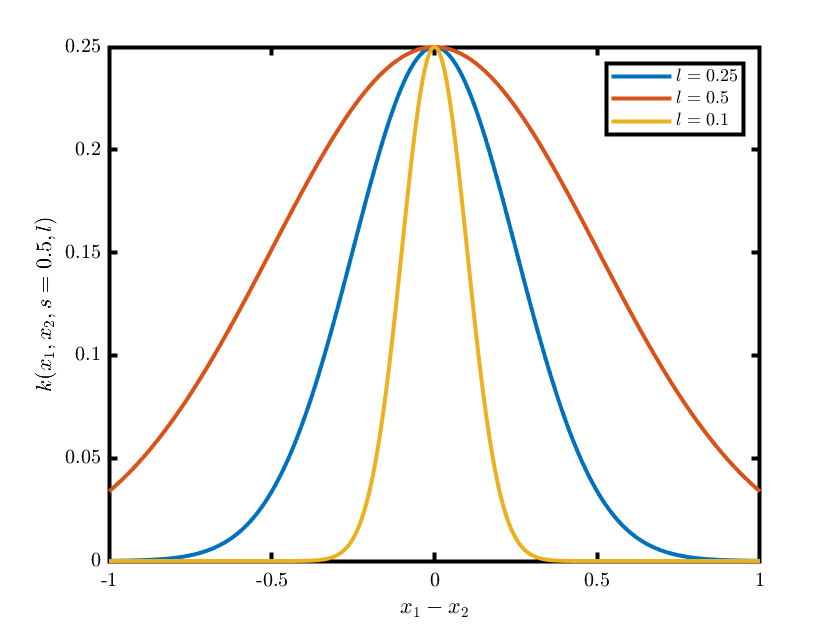

%now we'll show what happens when you vary the parameter l in the Radial Basis Function
x = linspace(-1,1,1000); 
s = .5; l1 = .25; l2 = .5; l3 = .1; 
figure(1)
    plot(x,kernel_fun3(x,0,s,l1),'LineWidth',2); hold on; 
    plot(x,kernel_fun3(x,0,s,l2),'LineWidth',2); hold on; 
    plot(x,kernel_fun3(x,0,s,l3),'LineWidth',2); hold on; 
    xlabel('$x_{1}-x_{2}$','Interpreter','latex'); ylabel(['$k(x_{1},x_{2},s = ',num2str(s),', l)$'],'Interpreter','latex'); 
    legend({['$l = ',num2str(l1),'$'],['$l = ',num2str(l2),'$'],['$l = ',num2str(l3),'$']},'Interpreter','latex'); 
    set(gca,'linewidth',2); hold off; 

The Matern kernels adds *pointyness* to the radial basis function. This allows them to approximate functions that have sharp features without having to change the value of *l. *This *pointyness *increases the correlation of points that are close together while maintaining the correlation of the points that are further apart. You can think of this as having the benefits of a large *l *in getting global information (points far apart) while having the benefits of a small *l *in weighing local information (points close together). 

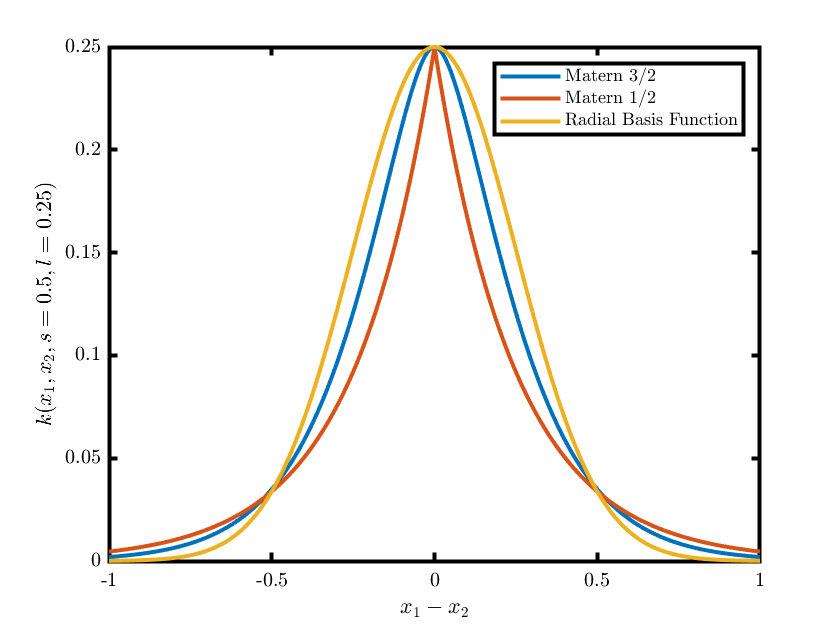

%plotting the kernel functions: 
x = linspace(-1,1,1000); 
s = .5; l = .25;
figure(1)
    plot(x,kernel_fun1(x,0,s,l),'LineWidth',2); hold on; 
    plot(x,kernel_fun2(x,0,s,l),'LineWidth',2); hold on; 
    plot(x,kernel_fun3(x,0,s,l),'LineWidth',2); hold on; 
    xlabel('$x_{1}-x_{2}$','Interpreter','latex'); ylabel(['$k(x_{1},x_{2},s = ',num2str(s),', l = ',num2str(l),')$'],'Interpreter','latex'); 
    legend({'Matern $3/2$','Matern $1/2$','Radial Basis Function'},'Interpreter','latex'); 
    set(gca,'linewidth',2); hold off; 

The periodic kernel is useful when your signal has known periodicity (Np). 

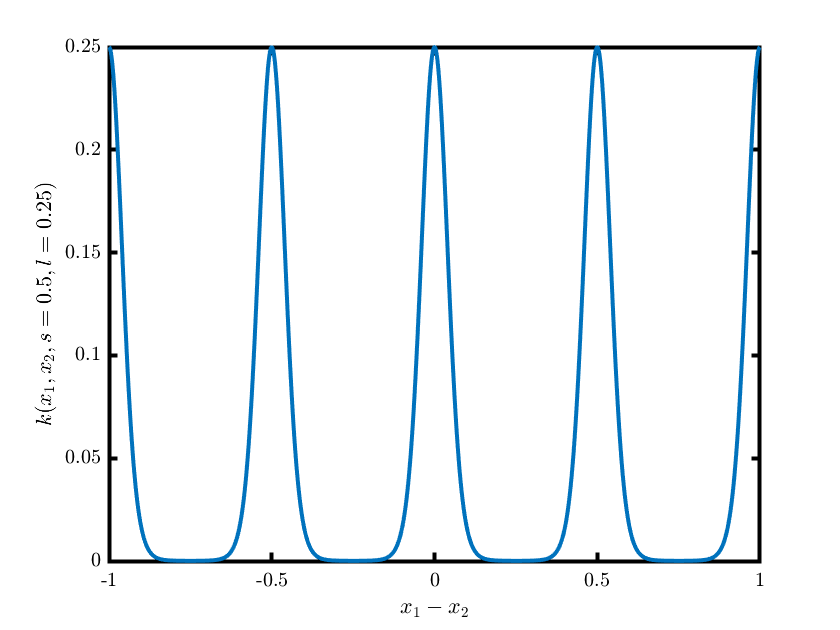

    %plotting the kernel functions: 
x = linspace(-1,1,1000); 
s = .5; l = .25;
figure(1)
    plot(x,kernel_fun5(x,0,s,l,2),'LineWidth',2); hold on; 
    xlabel('$x_{1}-x_{2}$','Interpreter','latex'); ylabel(['$k(x_{1},x_{2},s = ',num2str(s),', l = ',num2str(l),')$'],'Interpreter','latex'); 
    set(gca,'linewidth',2); hold off; 

If these kernel functions do not suffice, you can build your own kernel functions by multiplying kernel functions together, adding them together, etc. 

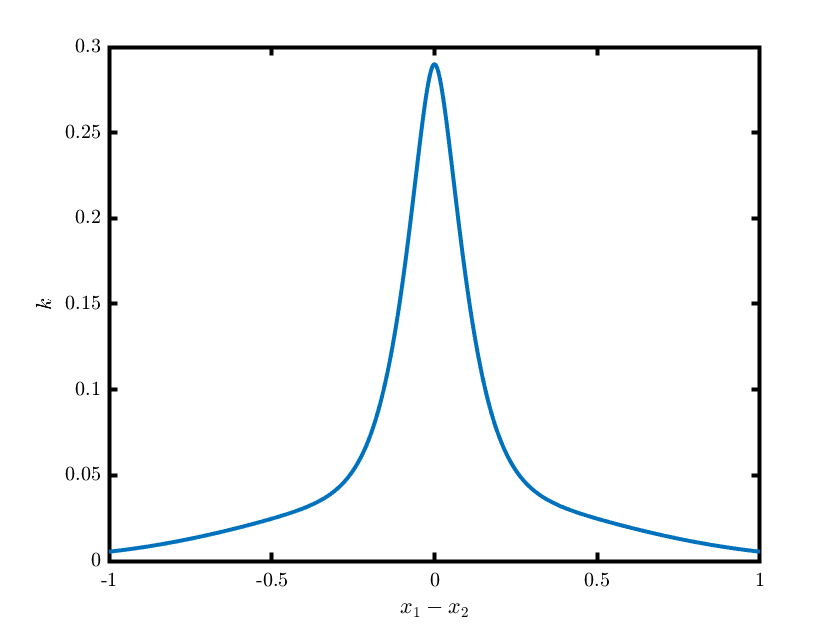

%example: 
    k_add = @(x1,x2,s,l,p,q) kernel_fun1(x1,x2,s,l) + kernel_fun3(x1,x2,p,q);
        plot(x,k_add(x,0,.5,.1,.2,.5),'LineWidth',2)
        xlabel('$x_{1}-x_{2}$','Interpreter','latex'); ylabel(['$k$'],'Interpreter','latex'); 
        set(gca,'linewidth',2); hold off; 

    %create your own kernels: 
    

## Kernel functions in practice: 

For the given parameters, the RBF does a lot better at approximating the sinusoidal input. However, when the function has an absolute value the Matern kernel does a better job at approximating the function. 

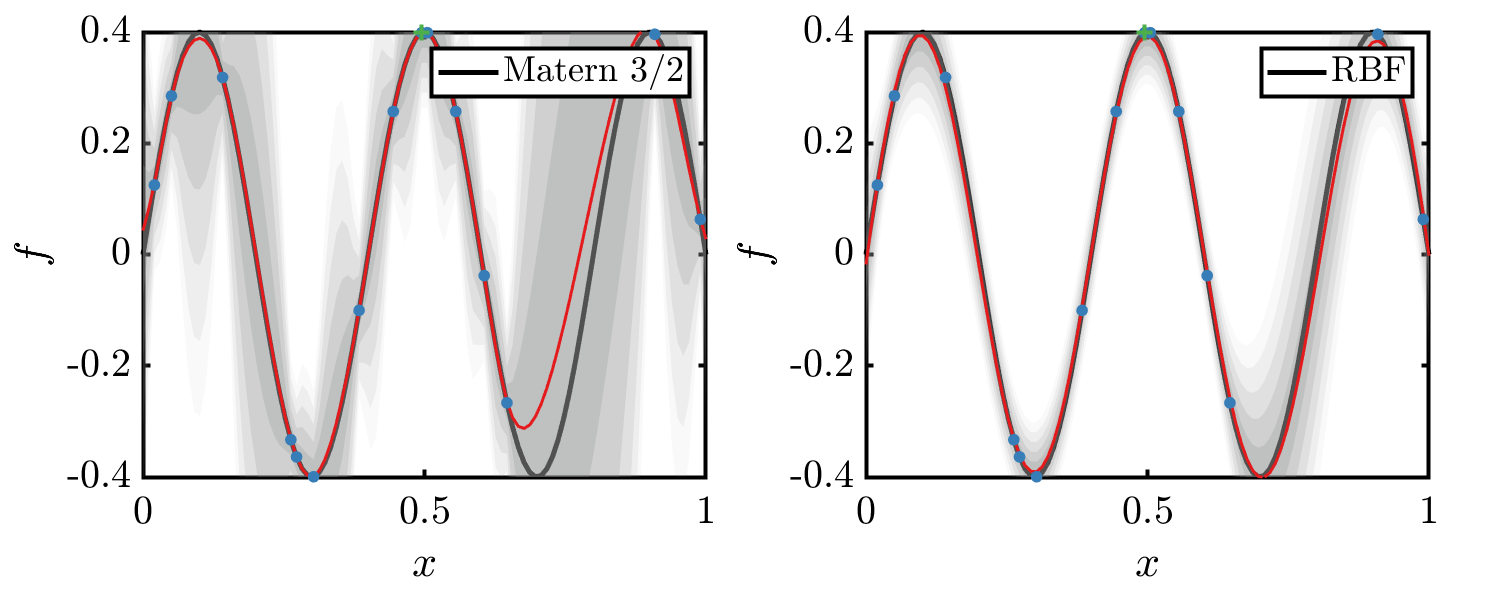

clear x_data y_data m_data
f          = @(x) .4*sin(5*pi*x) + 0*abs(5*(x-.5)); %function we want to model 
ftrue      = f(x);
x          = linspace(0,1,100)'; %points we'll use
rng(1)%seed we'll use
ii         = randperm(length(x))'; Num_Samples = 15; 
s = 1; l = .2; i = 10^-3;  %in practice, a robust code optimizes the choice os s and l and i 
figure()
tiledlayout(1,2,'TileSpacing','none','Padding',"compact");
nexttile
    %get data for the GPR:
    x0                     = x(ii(1:Num_Samples,1));
    eval                   = f(x0); %evaluate at sample point
    x_data                 = x0; 
    y_data                 = (eval); 
    m_data                 = [y_data];
    plot(x,ftrue,'LineWidth',2.5,'color','k'); ylim1 = ylim; hold on; %plot the actual data
    [mean_m, cov_m, var_m] = plot_results(x_data,m_data,x,s,l,i,kernel_fun1,0); %compute the GPR and plot
    xlabel('$x$','Interpreter','latex'); ylabel('$f$','Interpreter','latex'); ylim(ylim1)
    legend('Matern 3/2','interpreter','latex')
    set(gca,'LineWidth',2,'FontSize',20)
nexttile
    %get data for the GPR:
    x0                     = x(ii(1:Num_Samples));
    eval                   = f(x0); %evaluate at sample point
    x_data                 = x0; 
    y_data                 = (eval); 
    m_data                 = [y_data];
    plot(x,ftrue,'LineWidth',2.5,'color','k'); ylim1 = ylim; hold on; %plot the actual data
    [mean_m, cov_m, var_m] = plot_results(x_data,m_data,x,s,l,i,kernel_fun3,0); %compute the GPR and plot
    xlabel('$x$','Interpreter','latex'); ylabel('$f$','Interpreter','latex'); ylim(ylim1)
    set(gca,'LineWidth',2,'FontSize',20)
    legend('RBF','interpreter','latex')
    set(gcf,'position',[100,100,1000,400])

function [mean_m, cov_m, var_m] = plot_results(x_data,y_data,x,s,l,i,kernel_fun,Np)
%x_data is x locations of samples points, y_data is measurements at sampled points
%x is the data you wish to interpolate onto
%i is the regularizer
%if Np = 0 we are NOT using the periodic kernel. If Np > 0 it is number of
%periods expected in signal
%kernel_fun is the kernel function you want to use, takes in x1 and x2 as arguments
%Does the GPR and plots 
    if Np == 0
        %change nothing
    else
        kernel_fun = @(x1,x2,s,l) kernel_fun(x1,x2,s,l,Np); 
    end
    [mean_m, cov_m, var_m] = GPR(x_data,y_data(1:length(x_data),:),x,s,l,i,kernel_fun);
    std_m = sqrt(abs(real(var_m))); 
    x2 = [x,flip(x)];
    for ind1 = 1:5
        ind = 5-ind1+1;
        top = mean_m + ind*std_m; 
        bot = mean_m - ind*std_m; 
        inb = ([top;flip(bot)]);
        fill(x2(:),inb(:),[0.5569    0.5686    0.5608],'FaceAlpha',ind1*.05,'EdgeColor','none'); hold on;
    end
    hold on;
    colors = [0.8941    0.1020    0.1098;0.2157    0.4941    0.7216;0.3020    0.6863    0.2902;0.5961    0.3059    0.6392];%cbrewer('qual','Set1',4);%cbrewer('qual','Set1',4); 
%plotting:    
    plot(x,(mean_m),'LineWidth',1.5,'Color',colors(1,:))
    hold on; 
    plot(x_data,(y_data(1:length(x_data))),'.','LineWidth',2,'MarkerSize',20,'Color',colors(2,:))
    plot(x_data(end),(y_data(length(x_data))),'+','LineWidth',2,'MarkerSize',8,'Color',colors(3,:))
    xlabel('$x$','Interpreter','latex'); 
    set(gca,'LineWidth',2,'FontSize',18)
end

function [mean_at_values, cov_at_values, var_at_values] = GPR(xdata,ydata,x,s,l,i,kernel_fun)
%set up the kernels
    K  = covariance_matrix(xdata,xdata,s,l,kernel_fun);
    %the second term models noise and helps regularize the inversion
    Kl = chol(K + i*diag(ones(length(xdata),1)));
    Kli= inv(Kl);
    Ks = covariance_matrix(x,xdata,s,l,kernel_fun);
    Kss= covariance_matrix(x,x,s,l,kernel_fun);
%get the mean
    %mean_at_values = Ks*Ki*ydata(:); 
    mean_at_values = Kli'*ydata(:);
    mean_at_values = Kli*mean_at_values;
    mean_at_values = Ks*mean_at_values; 
%get the covariance
    KsKli = Ks*Kli;
    %cov_at_values  = Kss - Ks*Ki*(Ks)'; cov_at_values = (cov_at_values + (cov_at_values)')/2 + 0*eps*eye(size(cov_at_values));
    cov_at_values  = Kss - KsKli*KsKli';  cov_at_values = (cov_at_values + (cov_at_values)')/2;
    var_at_values  = diag(cov_at_values); 
    mean_at_values = mean_at_values(1:length(x));
    cov_at_values  = cov_at_values(1:length(x)); 
    var_at_values  = var_at_values(1:length(x)); 
end

function cov_mat = covariance_matrix(x1,x2,s,l,kernel_fun)
%covariance matrix without derivative info
    cov_mat1 = zeros(length(x1),length(x2));
    for ind1 = 1:length(x1)
        for ind2 = 1:length(x2)
            cov_mat1(ind1,ind2) = kernel_fun(x1(ind1),x2(ind2),s,l);
        end
    end
    cov_mat = cov_mat1; 
end

## Bayesian Optimization for GPR

- Discuss why it's needed, where it's used, how it compares to other methods

- Discuss the algorithm

- Discuss choice of acquisition functions